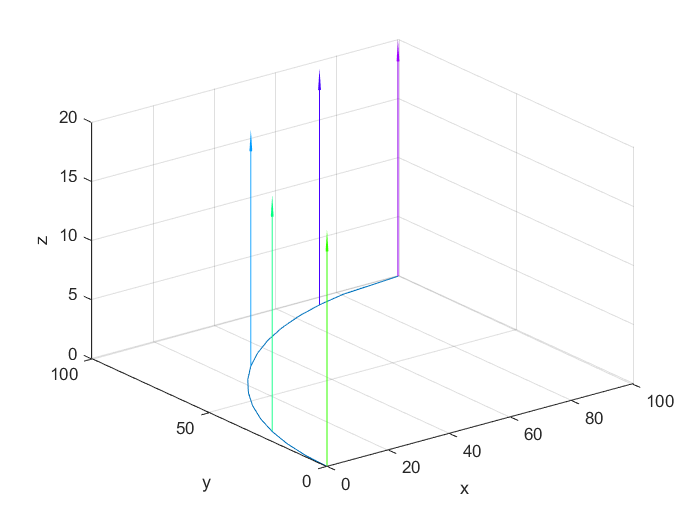

x = dlmread("xsegments.txt");
x = [0,x(1:end-1)];
y = dlmread("ysegments.txt");
y = [0,y(1:end-1)];
z = dlmread("zsegments.txt");
z = [0,z(1:end-1)];
I = dlmread("isegments.txt");
I = [0,I(1:end-1)];
J = dlmread("jsegments.txt");
J = [0,J(1:end-1)];
K = dlmread("ksegments.txt");
K = [1,K(1:end-1)];

figure;
plot3(x,y,z);
xlabel('x'),ylabel('y'),zlabel('z');
grid on;
hold on;
count = 5;
arrow_length = 20;
hsv(1,1,1) = 0.3; % hue
hsv(1,1,2) = 1; % saturation
hsv(1,1,3) = 1; % value
color_inc = 0.5/size(x,2);
Q = [x;y;z];
O = [I;J;K];
for i=1:size(x,2)
    rgb = hsv2rgb(hsv);
    if mod(i,count)==0|| i==1 || i==size(x,2)
        mArrow3(Q(:,i),Q(:,i)+arrow_length*O(:,i),'stemWidth',arrow_length*3/500,'color',rgb);
    end
    hsv(1,1,1) = hsv(1,1,1) + color_inc;
end